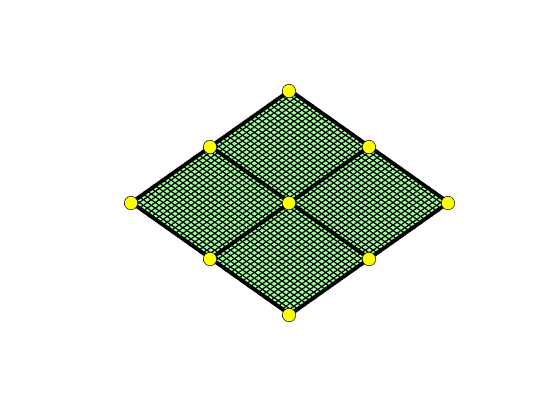

clear all;clc;close all

%%% Init corners
%%%%%%%%%%%%%%%%%%
% corners_mat = [2 1 2;
%                1 0 1;
%                2 1 2];

n_corners   = 3;
a           = -10;
b           = 10;
% corners_mat = a + (b-a)*rand(n_corners);

corners_mat = zeros(n_corners);

%%% Init vectors and matrix of coordinates
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
N        = 41;
xy       = 1:n_corners;
x        = linspace(1,n_corners,N);
y        = linspace(1,n_corners,N);
[X,Y]    = meshgrid(x,y);

%%% Generate tiles and compute gradient
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Z       = fun_tiles2D(x,y,corners_mat);
[gX,gY] = gradient(Z);
G       = sqrt(gX.^2+gY.^2);

%%% Init Figure
%%%%%%%%%%%%%%%%%%
% set(gcf,'Position',[0 0 1600 900]);set(gcf,'color','w');
hold on;pbaspect([1 1 0.75]);axis off
view(135,45)
axis([1 n_corners 1 n_corners a b]);
%%% Plot surface
%%%%%%%%%%%%%%%%%%
surface=surf(X,Y,Z,G);
surface.FaceColor='interp';
surface.EdgeColor='k';
surface.FaceAlpha=0.75;
surface.LineWidth=0.25;
colormap("jet")

%%% Plot tiles border
%%%%%%%%%%%%%%%%%%%%%%%%
xVertical   = [xy(1)*ones(1,N),NaN,xy(end)*ones(1,N),NaN];
yVertical   = [y              ,NaN,y                ,NaN];
xHorizontal = [x              ,NaN,x                ,NaN];
yHorizontal = [xy(1)*ones(1,N),NaN,xy(end)*ones(1,N),NaN];
xMedium     = [xy(2)*ones(1,N),NaN,x                ,NaN];
yMedium     = [y              ,NaN,xy(2)*ones(1,N)  ,NaN];
xlines      = [xVertical, xHorizontal, xMedium];
ylines      = [yVertical, yHorizontal, yMedium];
zlines      = interp2(X,Y,Z,xlines,ylines);
tilesBorder = plot3(xlines,ylines,zlines,'k',LineWidth=3);

%%%  Scatter corners values
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[Xxy,Yxy] = meshgrid(xy,xy);
corners = scatter3(Xxy(:),Yxy(:),corners_mat(:),MarkerFaceColor='y',MarkerEdgeColor='k',SizeData=100);

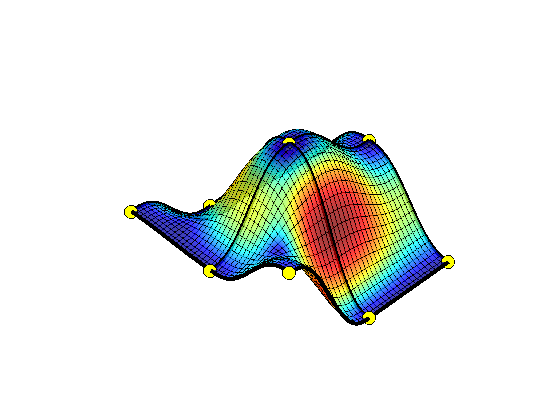


a11 = -10;
a21 = 1;
a31 = -10;
a12 = -10;
a22 = 10;
a32 = -10;
a13 = -1.5;
a23 = -2;
a33 = 7;

%%% update surface
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

corners_mat(:) = [a11 a21 a31 a12 a22 a32 a13 a23 a33];

Z             = fun_tiles2D(x,y,corners_mat);
[gX,gY]       = gradient(Z);
G             = sqrt(gX.^2+gY.^2);
surface.ZData = Z;
surface.CData = G;

%%% update tiles border
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zlines            = interp2(X,Y,Z,xlines,ylines);
tilesBorder.ZData = zlines;

%%% update corners
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
corners.ZData = corners_mat(:);